clc;

%% Radar Specifications 
%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Frequency of operation = 77GHz
% Max Range = 200m
% Range Resolution = 1 m
% Max Velocity = 100 m/s
%%%%%%%%%%%%%%%%%%%%%%%%%%%

%speed of light = 3e8
%% User Defined Range and Velocity of target
% *%TODO* :
% define the target's initial position and velocity. Note : Velocity
% remains contant
 Xt = 110;
 Vt = -20;


%% FMCW Waveform Generation

% *%TODO* :
%Design the FMCW waveform by giving the specs of each of its parameters.
% Calculate the Bandwidth (B), Chirp Time (Tchirp) and Slope (slope) of the FMCW
% chirp using the requirements above.
c = 3e8;
Rmax = 200;
Rres = 1;
B = c / (2 * Rres);
TripTime = 2 * Rmax;
Tchirp = 5.5 * (TripTime / c);
slope = B / Tchirp;

%Operating carrier frequency of Radar 
fc= 77e9;             %carrier freq

                                                          
%The number of chirps in one sequence. Its ideal to have 2^ value for the ease of running the FFT
%for Doppler Estimation. 
Nd=128;                   % #of doppler cells OR #of sent periods % number of chirps

%The number of samples on each chirp. 
Nr=1024;                  %for length of time OR # of range cells

% Timestamp for running the displacement scenario for every sample on each
% chirp
t=linspace(0,Nd*Tchirp,Nr*Nd); %total time for samples


%Creating the vectors for Tx, Rx and Mix based on the total samples input.
Tx=zeros(1,length(t)); %transmitted signal
Rx=zeros(1,length(t)); %received signal
Mix = zeros(1,length(t)); %beat signal

%Similar vectors for range_covered and time delay.
r_t=zeros(1,length(t));
td=zeros(1,length(t));


%% Signal generation and Moving Target simulation
% Running the radar scenario over the time. 

for i=1:length(t)         
    
    
    % *%TODO* :
    %For each time stamp update the Range of the Target for constant velocity. 
    r_t(i) = Xt + (Vt * t(i));
    td(i) = (2 * r_t(i)) / c;
    % *%TODO* :
    %For each time sample we need update the transmitted and
    %received signal. 
 
    tx_linear = fc * t(i);
    tx_quad = slope * power(t(i), 2) / 2;
    Tx(i) = cos(2 * pi * (tx_linear + tx_quad));

    tr = (t(i) - td(i));
    rx_linear = fc * tr;
    rx_quad = slope * power(tr, 2) / 2;
    Rx (i)  = cos(2 * pi * (rx_linear + rx_quad));
    
    % *%TODO* :
    %Now by mixing the Transmit and Receive generate the beat signal
    %This is done by element wise matrix multiplication of Transmit and
    %Receiver Signal
    Mix(i) = Tx(i) .* Rx(i);
    
end

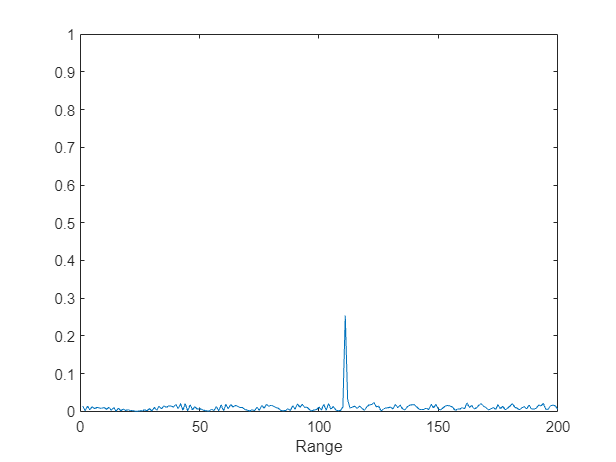

%% RANGE MEASUREMENT


 % *%TODO* :
%reshape the vector into Nr*Nd array. Nr and Nd here would also define the size of
%Range and Doppler FFT respectively.
Mix = reshape(Mix, Nr, Nd);
 % *%TODO* :
%run the FFT on the beat signal along the range bins dimension (Nr) and
%normalize.

fft1_signal = fft(Mix, Nr);
fft1_signal = fft1_signal ./ Nr;
 % *%TODO* :
% Take the absolute value of FFT output
fft1_signal = abs(fft1_signal);
 % *%TODO* :
% Output of FFT is double sided signal, but we are interested in only one side of the spectrum.
% Hence we throw out half of the samples.
fft1_signal = fft1_signal(1:Nr /2);

%plotting the range

figure ('Name','Range from First FFT')
 % *%TODO* :
 % plot FFT output 

plot(fft1_signal)
xlabel("Range")
axis ([0 200 0 1]);

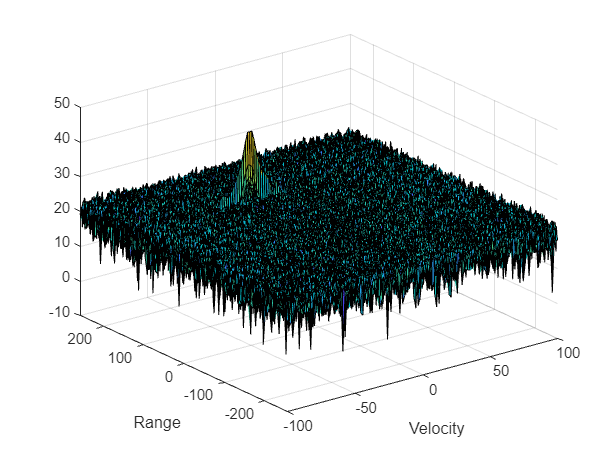



%% RANGE DOPPLER RESPONSE
% The 2D FFT implementation is already provided here. This will run a 2DFFT
% on the mixed signal (beat signal) output and generate a range doppler
% map.You will implement CFAR on the generated RDM


% Range Doppler Map Generation.

% The output of the 2D FFT is an image that has reponse in the range and
% doppler FFT bins. So, it is important to convert the axis from bin sizes
% to range and doppler based on their Max values.

Mix=reshape(Mix,[Nr,Nd]);

% 2D FFT using the FFT size for both dimensions.
sig_fft2 = fft2(Mix,Nr,Nd);

% Taking just one side of signal from Range dimension.
sig_fft2 = sig_fft2(1:Nr/2,1:Nd);
sig_fft2 = fftshift (sig_fft2);
RDM = abs(sig_fft2);
RDM = 10*log10(RDM) ;

%use the surf function to plot the output of 2DFFT and to show axis in both
%dimensions
doppler_axis = linspace(-100,100,Nd);
range_axis = linspace(-200,200,Nr/2)*((Nr/2)/400);
figure,surf(doppler_axis,range_axis,RDM);
xlabel("Velocity")
ylabel("Range")

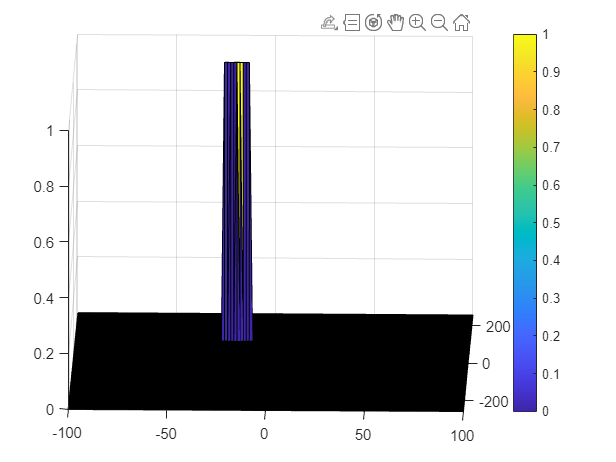

%% CFAR implementation

%Slide Window through the complete Range Doppler Map

% *%TODO* :
%Select the number of Training Cells in both the dimensions.
TR = 7;
Tc = 7;
% *%TODO* :
%Select the number of Guard Cells in both dimensions around the Cell under 
%test (CUT) for accurate estimation
GR = 2;
GC = 2;
% *%TODO* :
% offset the threshold by SNR value in dB

% *%TODO* :
%Create a vector to store noise_level for each iteration on training cells

% *%TODO* :
%design a loop such that it slides the CUT across range doppler map by
%giving margins at the edges for Training and Guard Cells.
%For every iteration sum the signal level within all the training
%cells. To sum convert the value from logarithmic to linear using db2pow
%function. Average the summed values for all of the training
%cells used. After averaging convert it back to logarithimic using pow2db.
%Further add the offset to it to determine the threshold. Next, compare the
%signal under CUT with this threshold. If the CUT level > threshold assign
%it a value of 1, else equate it to 0.


% Use RDM[x,y] as the matrix from the output of 2D FFT for implementing
% CFAR

%create matrix of training cells
offset = 5;
PRows = TR + GR; % Padding along rows
PCols = TC + GC; % Padding along cols

total_block_cells = (2 * (TR + GR) + 1) * (2 * (TC + GC) + 1);
cut_cells = (2 * GR + 1) * (2 * GC + 1); % CUT + guard cells
num_training_cells = total_block_cells - cut_cells;
% Get the full block of size [TD, TR]


row_start = (TR + GR) + 1;
row_end = Nr/2 - (TR + GR);
col_start = (TC + GC) + 1;
col_end = Nd - (TC + GC);

cfar_signal = zeros(size(RDM));
for i = row_start:row_end
    for j = col_start: col_end
        
        % Get the full block sum
        full_block_sum = sum(db2pow(RDM(i - (PRows): i + PRows, j - PCols : j + PCols)), "all");
        % find the training block sum by removing the effect of CUT + Guard
        cut_block_sum = sum(db2pow(RDM(i - GR:i + GR, j - GC: j + GC)), "all");
        noise_level = full_block_sum - cut_block_sum;
        threshold = db2pow(pow2db(noise_level / num_training_cells) + offset);

        rdm_signal = db2pow(RDM(i, j));
        cfar_signal(i, j) = rdm_signal > threshold;

    end
end

% *%TODO* :
% The process above will generate a thresholded block, which is smaller 
%than the Range Doppler Map as the CUT cannot be located at the edges of
%matrix. Hence,few cells will not be thresholded. To keep the map size same
% set those values to 0. 

% This TODO is already handled as the cfar_signal matrix is zero
% initialized

% *%TODO* :
%display the CFAR output using the Surf function like we did for Range
%Doppler Response output.
figure,surf(doppler_axis,range_axis, cfar_signal);
colorbar; 